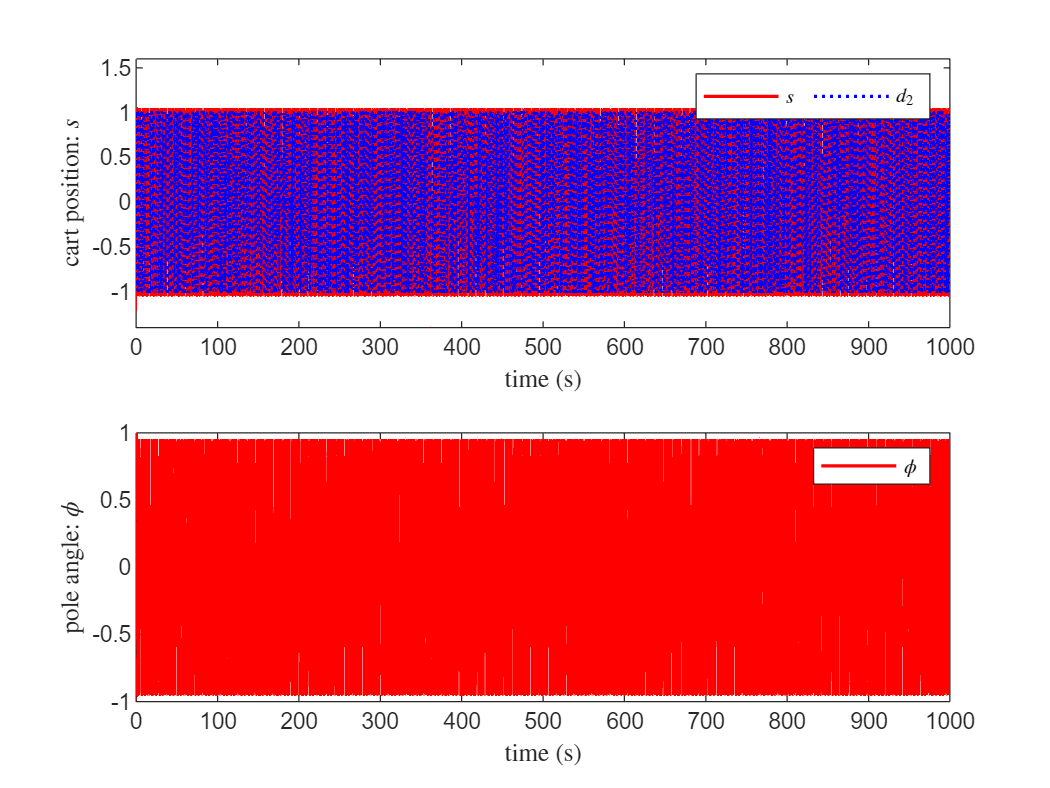

% B2
% plot the graphs
% workspace
time = out.tout;

d1 = out.noise.signals(1).values;
d2 = out.reference_signal.signals(1).values;

control_input = out.B2_control_input.signals(1).values;

s_t = out.yt.signals(1).values(:,1);
phi_t = out.yt.signals(1).values(:,2);

figure
subplot(2,1,1);
plot(time,s_t,Color='r',LineWidth=1.3)
hold on
plot(time,d2,Color='b',LineWidth=1.3,LineStyle=':')
xlabel('time (s)','interpreter','latex', 'FontWeight','bold');
ylabel('cart position: $s$','interpreter','latex', 'FontWeight','bold');
legend('$s$', '$d_2$','interpreter','latex', 'FontWeight','bold','Orientation','horizontal');
ylim([-1.4,1.6])

subplot(2,1,2);
plot(time,phi_t,Color='r',LineWidth=1.3)
xlabel('time (s)','interpreter','latex', 'FontWeight','bold');
ylabel('pole angle: $\phi$','interpreter','latex', 'FontWeight','bold');
legend('$\phi$','interpreter','latex', 'FontWeight','bold','Orientation','horizontal');

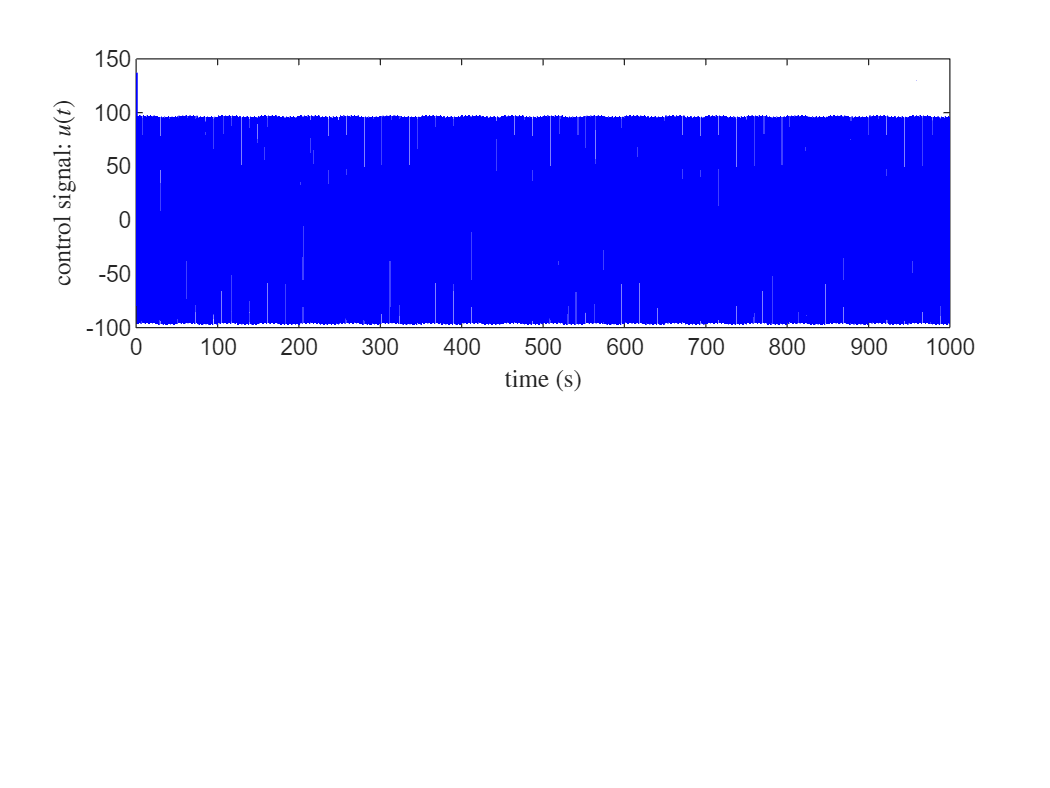


% exportgraphics(gcf,'linear_yt_omega=10.png','Resolution',330)

figure
subplot(2,1,1)
plot(time,control_input,Color='b',LineWidth=1.3)
xlabel('time (s)','interpreter','latex', 'FontWeight','bold');
ylabel('control signal: $u(t)$','interpreter','latex', 'FontWeight','bold');

error_linear = -1.9883e-04

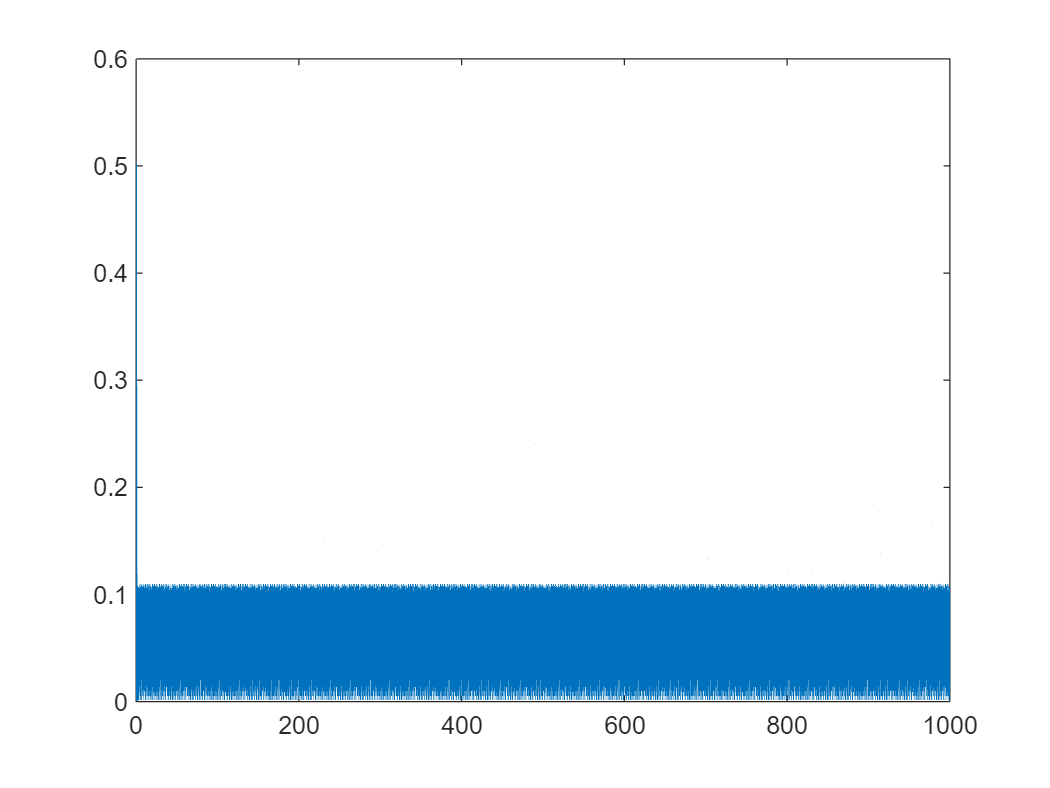

% exportgraphics(gcf,'linear_ut_omega=10.png','Resolution',330)

% figure

% error_linear = mean(s_t - d2)
% plot(time,abs(s_t - d2))